Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'purelin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    25



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0147



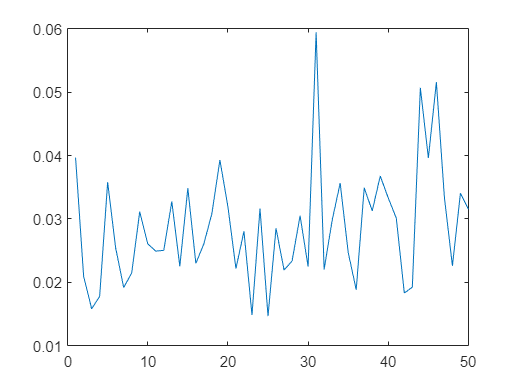

hold off;

net1 = fitnet(25,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 25
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'purelin';

[net1,tr1] = train(net1,pn,tn);


output_ANN1 = poslin(pn)

output_ANN1 =     0.4940    0.5061    0.4957    0.5235    0.5186    0.5196    0.5371    0.5317    0.5358    0.7044    0.7129    0.7004    0.7250    0.7153    0.7104    0.7343    0.7327    0.7246    0.9065    0.9172    0.9110    0.9181    0.9137    0.9149    0.9145    0.9350    0.9294    1.0010    0.9994    0.9956    0.1890    0.1869    0.1812    0.1908    0.1795    0.1680    0.3081    0.2956    0.2985    0.3034    0.2873    0.2944    0.3149    0.2922    0.2902    0.4228    0.4185    0.4192    0.4287    0.4184
    0.0324    0.5133    0.6771    0.0324    0.4580    0.7165    0.1142    0.4341    0.7779    0.0513    0.6364    0.6179    0.0267    0.4782    0.6817    0.1434    0.4747    0.8082    0.0690    0.7469    0.5259    0.0021    0.4471    0.4857    0.1666    0.4851    0.7451    0.0583    0.6058    0.5923    0.0419    0.5418    0.6804    0.1731    0.5535    0.7504    0.0632    0.6765    0.5261    0.0469    0.5959    0.5797    0.2054    0.5345    0.6619    0.0243    0.7775    0.4481    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   116.9031  118.1683  117.0788  119.9940  119.4740  119.5799  121.4138  120.8481  121.2823  138.9165  139.8031  138.4952  141.0666  140.0510  139.5431  142.0485  141.8813  141.0241  160.0570  161.1754  160.5243  161.2703  160.8110  160.9380  160.8956  163.0344  162.4497  169.9471  169.7814  169.3840   85.0045   84.7772   84.1877   85.1891   84.0054   82.8016   97.4575   96.1476   96.4570   96.9718   95.2878   96.0284   98.1684   95.7955   95.5910  109.4576  109.0024  109.0773  110.0753  109.0016


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.7777    1.4931    1.7367    0.7778    1.4108    1.7953    0.8995    1.3753    1.8867    0.8059    1.6761    1.6486    0.7693    1.4408    1.7435    0.9429    1.4357    1.9317    0.8323    1.8405    1.5118    0.7328    1.3946    1.4521    0.9774    1.4512    1.8379    0.8163    1.6307    1.6106    0.7919    1.5356    1.7417    0.9871    1.5529    1.8457    0.8236    1.7358    1.5122    0.7994    1.6160    1.5919    1.0351    1.5247    1.7141    0.7658    1.8861    1.3961    0.7342    1.7142


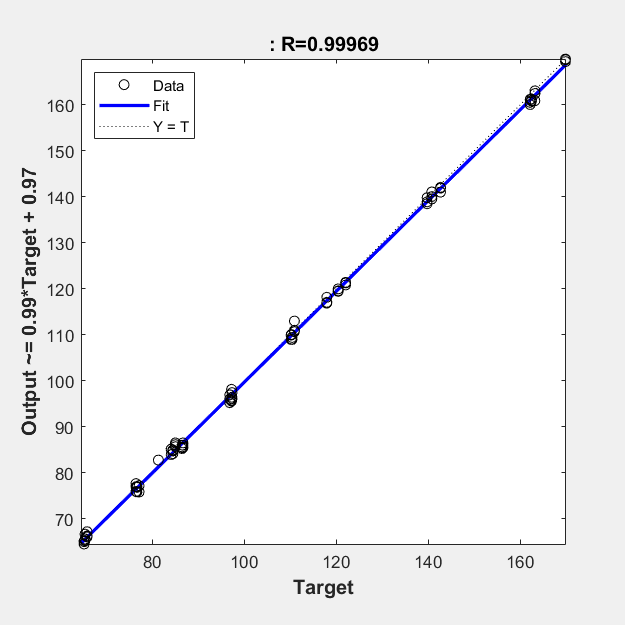

plotregression(t1,ANNIPF)

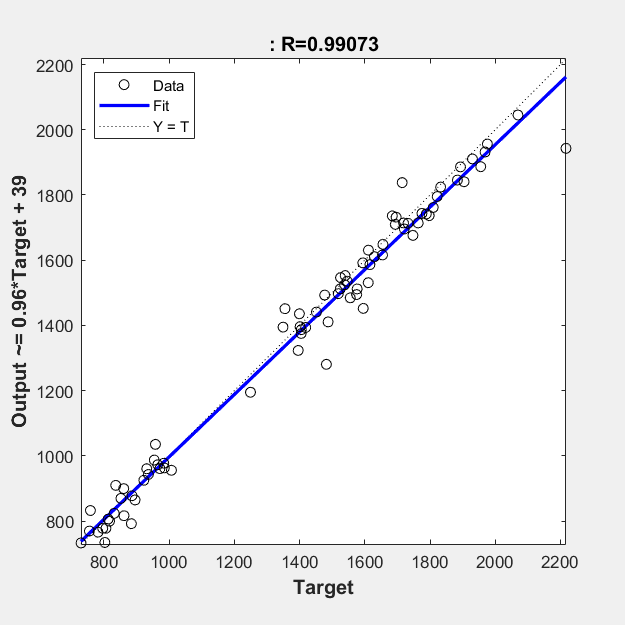

plotregression(t2,ANNSEA)

%plotregression(t1,output_ANN1(1,:));
%plotregression(t2,output_ANN1(2,:));

pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.7033
    0.4865



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 138.7970

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.4532e+03

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.